# Reference Area from GNSS Stations

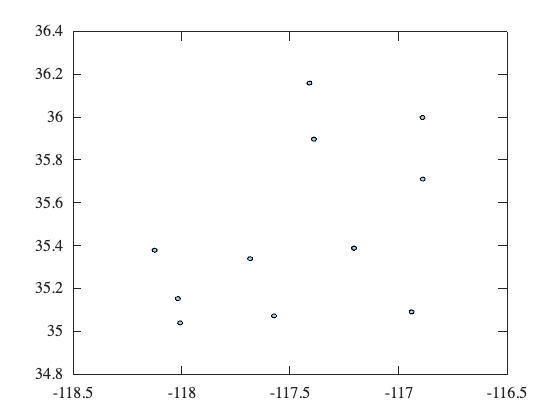


workdir= readlines("workdir.txt","EmptyLineRule","skip");


GNSSdir= fullfile(workdir,'GNSS');
refStationsFile= fullfile(GNSSdir,'referenceStations.txt');

StationID= readlines(refStationsFile,"EmptyLineRule","skip");

rejectedGNSSfile= fullfile(GNSSdir,"rejectedGNSSstations.txt");
if exist(rejectedGNSSfile,'file')
    rejectedStations= readlines(rejectedGNSSfile,"EmptyLineRule","skip");
    
    StationID= setdiff(StationID,rejectedStations);
end

UNRStations= gnss.downloadUNRStations;
[~,ia]= intersect(UNRStations.ID,StationID);

StationLongitude= UNRStations.Longitude(ia);
StationLatitude= UNRStations.Latitude(ia);

Nstations= length(StationID);

Npoints= 30;
az= (1:Npoints)*(360/Npoints);


DistanceMeters= 1000;
DistanceDegrees= DistanceMeters/111000;

LAT2= zeros(Nstations,Npoints);
LONG2= zeros(Nstations,Npoints);
for i= 1:Nstations
    [lat2,long2]= reckon(StationLatitude(i),StationLongitude(i),DistanceDegrees,az);
    LAT2(i,:)= lat2;
    LONG2(i,:)= long2;
end

ReferenceLongitude= reshape([LONG2 nan(Nstations,1)]',[],1);
ReferenceLatitude= reshape([LAT2 nan(Nstations,1)]',[],1);

plot(polyshape(ReferenceLongitude,ReferenceLatitude))
plt.pltOptions
box on

 

GEdir= fullfile(workdir,"Google Earth");
if ~exist(GEdir,'dir')
    mkdir(GEdir)
end

referenceAreaKMZFilename= fullfile(GEdir,"referenceArea.kmz");

kmz.writeKMZPolygon(referenceAreaKMZFilename,ReferenceLongitude,ReferenceLatitude,"Reference Area");